# Homework 6

## Due Wednesday, May 12 before 5:00pm CDT

*Using [Live Editor > Save > Export to PDF] to prepare your submission for Gradescope.*

## Fitting a nonlinear function

Let's create a highly nonlinear function and try to fit it using polynomial regression or an artifical nerual network.

First we set the seed of the random number generator. This ensures that we the same function whenever we run this file. The random number generator is used to initialize the training for the neural network.

rng(210);

Now let's create and plot the nonlinear function


$$y = e^{-x}\cos(3.25x^2) + e^{0.34x}\sin(x)$$


over the interval $[0,3]$.

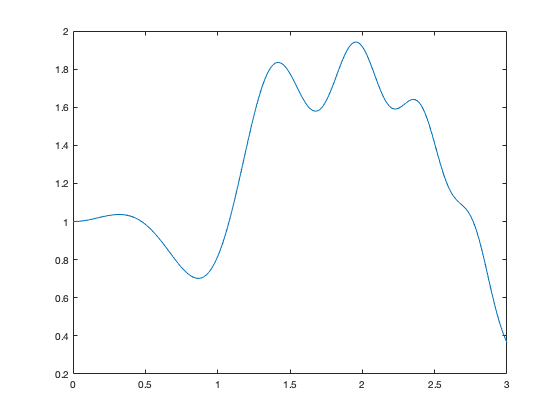

x = 0:0.01:3;
y = exp(-x) .* cos(3.25*x.^2) + exp(0.34*x).*sin(x);
plot(x,y)

Clearly there is a complex relationship between the input $x$ and the output $y$. We have 301 sample points (the size of the variable `x`) that we can use to fit a function.

## Polynomial Regression

Let's begin with polynomial regression. You already know how to use linear regression to fit polynomials. There is a shortcut function `polyfit` in Matlab that fits an $n$-degree polynomial. The `polyfit` function returns the coefficient vector ($\beta$), and we can use this vector in the `polyval` function to evaluate the polynomial at a point $x$. Let's start with a 10th-order polynomial.

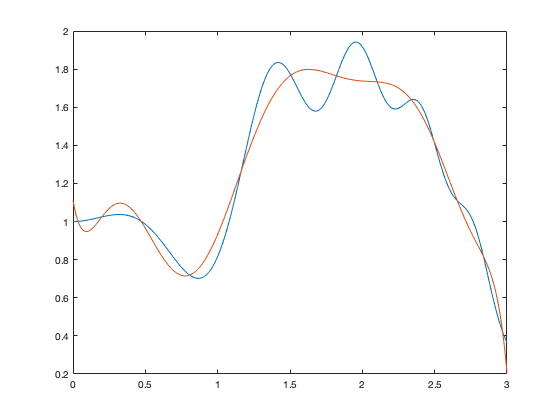

n = 10;
p = polyfit(x,y,n);
plot(x,y, x,polyval(p,x))

A 10th-degree polynomial is already ridiculous for a 1-dimensional function on a finite domain. However, the polynomial is still not a great match for our nonlinear function. Try increasing the degree of the polynomial until you achieve a good fit. Be warned -- you might run into numerical difficulties as the degree of the polynimal increases.

**Question 1: Think back to setting up the design matrix for polynomial regression. Why would you expect that fitting high-degree polynomials is numerically unstable?**

*<insert your answer here>*

## Artificial Neural Networks

Now let's try using a neural network to fit the same data. The networks we discussed in lecture are feed-forward networks since the output of each layer does not feed back into the previous layers. Our first attempt is a network with a single hidden layer with 12 nodes, which we create with the `feedforwardnet` function.

net = feedforwardnet([12]);
view(net)

The view function visualizes our neural network. We see our one hidden layer with 12 nodels. Matlab also adds an output layer that collects our output into a scalar. Inside the hidden layer we see three items: a matrix of weights ($\mathbf{W}$), the affine or "bias" term ($\mathbf{b}$), and the sigmoid nonlinear activation function. If we call the nonlinear function $f$ and the input to the layer $\mathbf{x}$, then the output of the layer is


$$f(\mathbf{W}\mathbf{x}+\mathbf{b})$$


**Question 2: What are the dimensions of **$\mathbf{W}$** and **$\mathbf{b}$**? Remember that our function is scalar-valued, i.e. the input **$\mathbf{x}$** is a 1-dimensional vector.**

*<insert your answer here>*

It can be difficult to count the total number of parameters in a neural network since the output layer also includes weights and a bias. The easiest method is to ask our network directly.

net.numWeightElements

ans = 12

Now let's train our neural network with the aptly named `train` function.

net = train(net,x,y);

You can explore the training parameters in the popup window.

After the network is trained we can use it to predict outputs. Let's plot the original function and the neural network approximation.

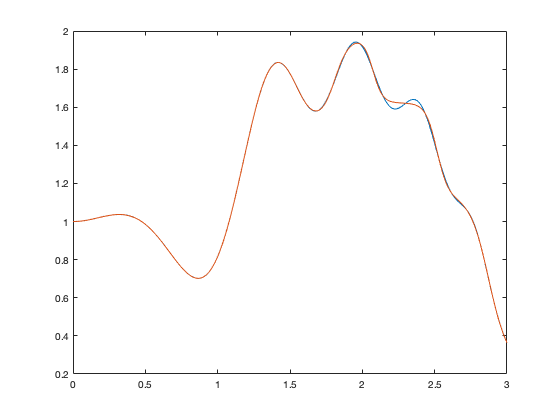

plot(x,y, x,net(x))

This network did a nice job, but it missed one of the shoulders in the data. We could expand the number of nodes in our single hidden layer. This would increase the number of parameters and would likely improve the results.

**Question 3: Try increasing the number of nodes until the neural network matches the original function. How many parameters are in this network?**

*<insert your answer here>*

Another strategy for improving the power of neural networks is to increase the number of layers. Adding layers makes the network a "deep neural network". Usually the same number of nodes are more predictive if they are split into multiple layers. For example, instead of using a single layer with 12 nodes we can split it into two layers with 8 and 4 nodes.

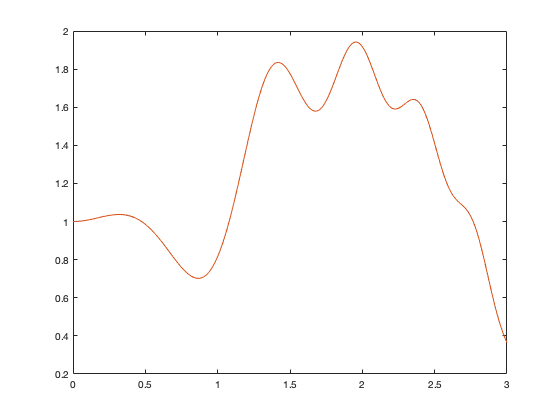

net2 = feedforwardnet([8 4]);
net2 = train(net2,x,y);
plot(x,y, x,net2(x))

You might have noticed that deep networks usually take longer to train. The updates to the weights must percolate back from the output to the input, and this takes longer when there are more layers.

**Question 4: Try altering the number of layers and the number of nodes in each layer. How small can you make the total number of nodes and still get a good approximation of the function?**

*<insert your answer here>*